In this file, we compare the standard MC and vectorized MC on a numerical case study. A disruptive event occurs following a poisson process. Once it happens, a safety barrier could contain its impact. If successful, it is performance degradation state; if not, it is total failure state (an absorption state). State probability is considered as performance indicators.

## Set up the case study

% This is a test of the simulation algorithm for inhomogeneous semi-Markov process.
% Invere cdf based on interpolation is used to sample the holding time distribution.
% Benchmark: A three state system, where state transitions are caused by
% arrival of disruptive events, performance of safety barriers, and
% recovery time distributions.
%            State 1: Perfect
%            State 2: Performance degradation.
%            State 3: Total failure (absorption state).
% Last edit: 20200705 - Remove the dummy state.
%            20200128 - Add comments.
%            20191223 - Created by ZZ
clear; clc;
addpath('../')
%% Parameter definition
% First arrival time of the disruptive event
lambda_D = 1e-3;
pd_disp = makedist('exponential','mu',1/lambda_D);
% Safety barriers
p_large = 1.6e-3; % Probability of large damage, leading to state 3
eta_s = 100; beta_s = 2;
pd_t_f_s = makedist('weibull','a',eta_s,'b',beta_s); % Time to failure distribution of the safety barrier
% Time to repair distribution
eta_r = 1; beta_r = 2;
pd_t_r = makedist('weibull','a',eta_r,'b',beta_r); 

% Simulation to calculate p(t) for each state, for 0<t<T_max
evaluation_horizon = 1e3;
t = linspace(.1,evaluation_horizon,10); % Evaluate time

ns = 1e6; % Sample size

% Create benchmark
p_t_ref = zeros(3,length(t)); % p(t): 3*1, each column corresponds to one state
sample_path = cell(1,ns); % Store all the sample path up to evaluation_horizon.
sample_jump_time = cell(1,ns); % Store all the jump times up to evaluation_horizon.

## Standard MC

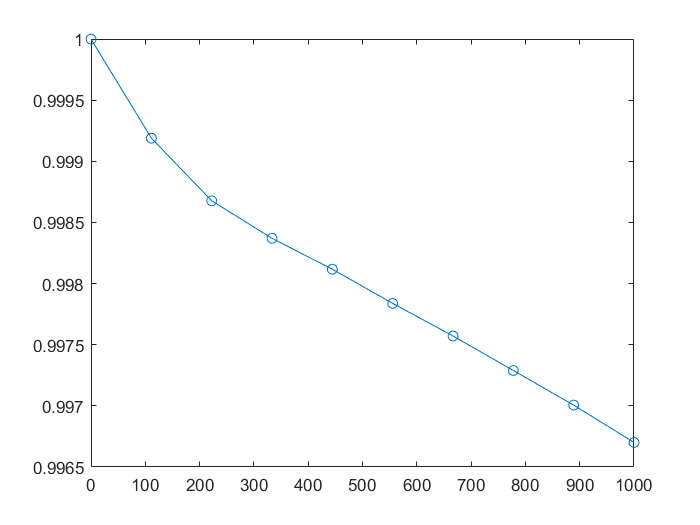

% tic;
% for j = 1:ns
%     t_cur = 0; % Initial value of time
%     state = 1; % Start from working
%     
%     % Initialize
%     temp_sample_path = -1*ones(1,1000); % Vector for the sample path.
%     temp_sample_jump_time = -1*ones(1,1000); % Vector for the sample path.
%     
%     index = 1; % Intial value for the index of the states.
%     temp_sample_path(index) = 1; 
%     temp_sample_jump_time(index) = 0; 
%     
%     while 1
%         index = index + 1; % Next state.
%         switch state
%             case 1 % If current state is perfect state
%                 theta = pd_disp.random(); % Interarrival time
%                 t_next = t_cur + theta; % Calculate the event occurrence tiem
%                 if t_next > evaluation_horizon % Beyond evaluation horizon
%                     t_cur = evaluation_horizon;
%                     
%                     temp_sample_path(index) = state;
%                     temp_sample_jump_time(index) = t_cur;
%                     break;
%                 else
%                     t_cur = t_next;
%                     % Decide what is the next state
%                     is_large_damage = binornd(1,p_large);
%                     is_fail_sb = binornd(1,pd_t_f_s.cdf(t_cur));                     
%                     if is_large_damage == 1 % If large damage happens
%                         state = 3; % Absorption state
%                     else
%                         if is_fail_sb == 1 % If safety barrier fails
%                             state = 2; % Degradation state
%                         else % If safety barrier is OK
%                             state = 1; % Still OK.
%                         end
%                     end
%                                         
%                     temp_sample_path(index) = state;
%                     temp_sample_jump_time(index) = t_cur;
%                 end
%             case 2
%                 theta_d = pd_disp.random(); % The next degradation time
%                 theta_r = pd_t_r.random(); % The next recovery time
%                 if theta_d < theta_r % If next transition is degradation
%                     theta = theta_d;
%                     t_next = t_cur + theta; % Calculate the event occurrence tiem
%                     if t_next > evaluation_horizon % Beyond evaluation horizon
%                         t_cur = evaluation_horizon;                                               
%                                             
%                         temp_sample_path(index) = state;
%                         temp_sample_jump_time(index) = t_cur;
%                         break;
%                     else
%                         t_cur = t_next;
%                         state = 3;                        
%                                             
%                         temp_sample_path(index) = state;
%                         temp_sample_jump_time(index) = t_cur;
%                     end
%                 else % If next state is recovery
%                     theta = theta_r;
%                     t_next = t_cur + theta; % Calculate the event occurrence tiem
%                     if t_next > evaluation_horizon % Beyond evaluation horizon
%                         t_cur = evaluation_horizon;                      
%                                             
%                         temp_sample_path(index) = state;
%                         temp_sample_jump_time(index) = t_cur;
%                         break;
%                     else
%                         t_cur = t_next;
%                         state = 1;
%                                             
%                         temp_sample_path(index) = state;
%                         temp_sample_jump_time(index) = t_cur;
%                     end
%                 end
%             case 3
%                 t_cur = evaluation_horizon;                             
% 
%                 temp_sample_path(index) = state;
%                 temp_sample_jump_time(index) = t_cur;
%                 break;                    
%             otherwise
%                 error('Undefined state!')
%         end            
%     end
%     
%     temp_sample_path = temp_sample_path(1:index);
%     temp_sample_jump_time = temp_sample_jump_time(1:index);
%     sample_path{j} = temp_sample_path;
%     sample_jump_time{j} = temp_sample_jump_time;
% end
% 
% %% Post processing.
% for i = 1:length(t)
%     tt = t(i);
%     count = zeros(1,3);
%     for j = 1:ns
%         temp_sample_path = sample_path{j};
%         temp_sample_jump_time = sample_jump_time{j};
%         
%         index = find(temp_sample_jump_time<tt,1,'last');
%         count(temp_sample_path(index)) = count(temp_sample_path(index)) + 1;        
%     end
%     p_t_ref(:,i) = transpose(count/ns);
% end
% 
% elapsed_time_1 = toc;
% save('result_ref.mat');

load('result_ref.mat');

% Display results
h_p_1 = figure();
plot(t,p_t_ref(1,:),'-o')
hold on

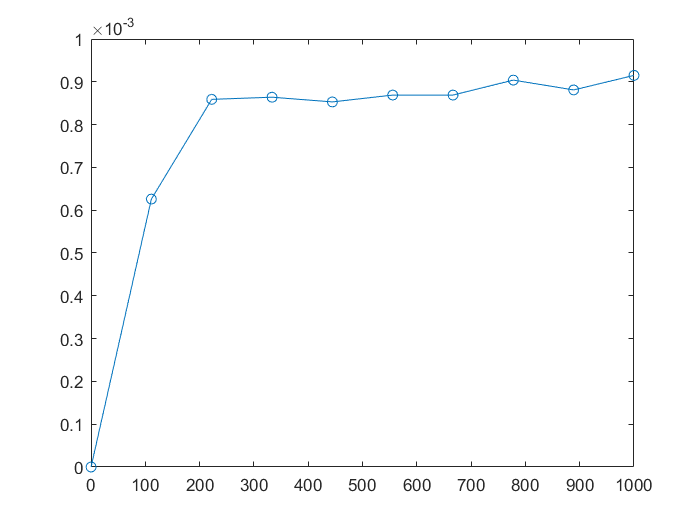

h_p_2 = figure();
plot(t,p_t_ref(2,:),'-o')
hold on

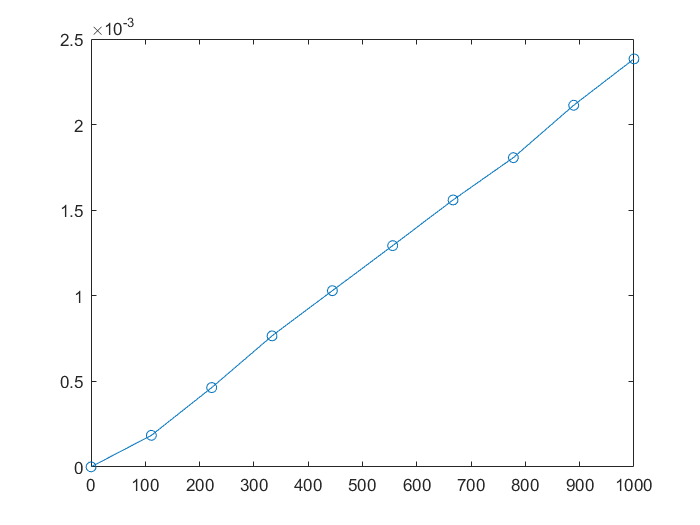

h_p_3 = figure();
plot(t,p_t_ref(3,:),'-o')
hold on
hold on

## Vectorized MC

%% Simulate using holding time distribution and embedded chain. Sampling with rejection method.
load('inv_cdf.mat','inv_cdf_f_02', 'inv_cdf_f_20');
% Define the embedded chain and the holding time dist.
pi_0 = [1,0,0]; % Initial distribution

% Elements in the transition probability matrix
p_01 = @(tau) 0.9984E0+0.887024E-1.*exp(1).^((1/1000).*tau).*((-0.1E1)+...
    erf(0.5E-1+ 0.1E-1.*tau));
p_02 = @(tau) .16e-2*ones(size(tau));
p_00 = @(tau) 1 - p_01(tau) - p_02(tau);
p_10 = @(tau) .999114*ones(size(tau));
p_12 = @(tau) 1 - p_10(tau);

% Handles to the transition probability matrix for each state: Returns a
% n_t*4 matrix, where each row is the transition probability vector
% p_{i,j}, j = 0,1,2,3, and the column represents the current time tau.
cal_p_tr_0 = @(tau) [p_00(tau), p_01(tau), p_02(tau)];
cal_p_tr_1 = @(tau) [p_10(tau), zeros(size(tau)), p_12(tau)];
cal_p_tr_2 = @(tau) [zeros(size(tau)), zeros(size(tau)), ones(size(tau))];
cal_p = {cal_p_tr_0, cal_p_tr_1, cal_p_tr_2};

% Random number generator of the holding times.
rnd_theta_01 = @(tau) rnd_theta_01_cal(tau,inv_cdf_f_02,evaluation_horizon);
rnd_theta_10 = @(tau) rnd_theta_10_cal(tau,inv_cdf_f_20,evaluation_horizon);

handle_zero = @(tau) zeros(size(tau));
rnd_matrix_theta = {@rnd_theta_00, rnd_theta_01, @rnd_theta_02;...
    rnd_theta_10, handle_zero, @rnd_theta_12;...
    handle_zero, handle_zero,handle_zero};

% Calculate the same probability distribution
fprintf('\n Embedded chain approach\n')


 Embedded chain approach


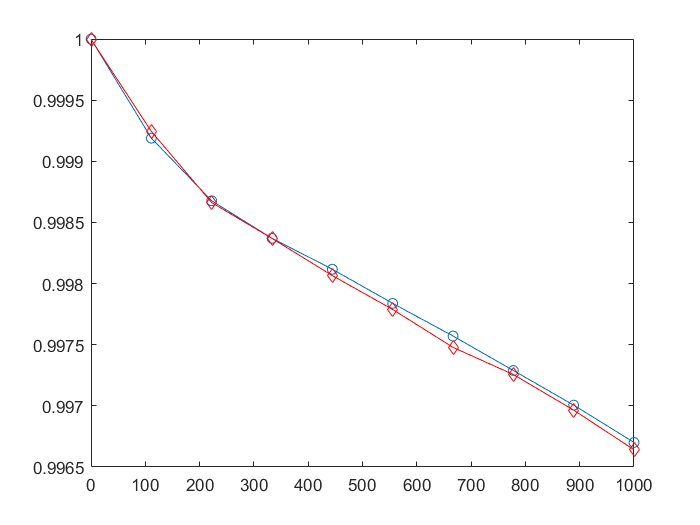

n_state = 3;
p_t_int = zeros(n_state,length(t)); % p(t): 4*1, each column corresponds to one state
max_n_jump = -1; % The maximum number of jumps considered.

tic;
% y and tau are matrix with dimension ns*(n_jump+1).
% Row of y represents the state after each jump, from 0 (initial values) to n_jump.
% Row of tau represents the occurrence time after each jump.
[y, tau] = simulate_semi_nhsmp_embedded(ns, max_n_jump, evaluation_horizon, ...
    pi_0, cal_p, rnd_matrix_theta);
y_transpose = y';

% Post-processing: Get the probability for each time epoch.
for i = 1:length(t)
    tt = t(i);
    
    % The last element in each row, where tau<tt
    offset_y = findfirst(tau<tt, 2, 1, 'last');
    loc_y = transpose(0:ns-1)*size(y,2) + offset_y;    
    
    % Get state at tt
    y_tt = y_transpose(loc_y);
    
    % Count numbers at each state and calculate the probability.
    bin_edge = 1:n_state+1;
    p_t_int(:,i) = transpose(histcounts(y_tt, bin_edge))/ns;
end

elapsed_time_2 = toc;

% Display results
figure(h_p_1);
plot(t,p_t_int(1,:),'-dr')

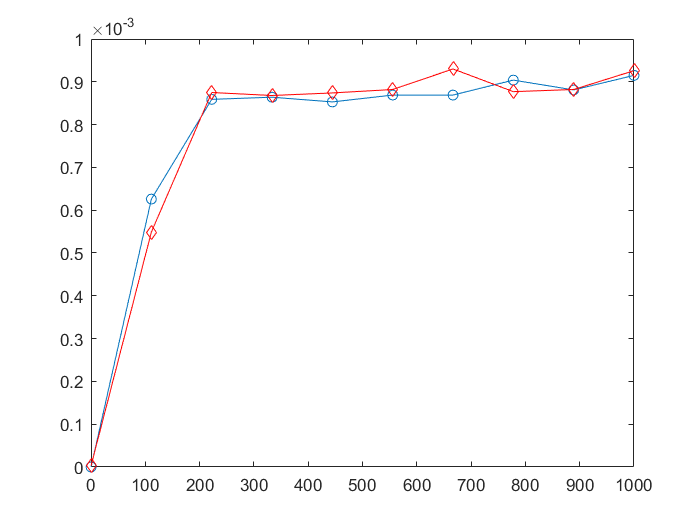

figure(h_p_2);
plot(t,p_t_int(2,:),'-dr')

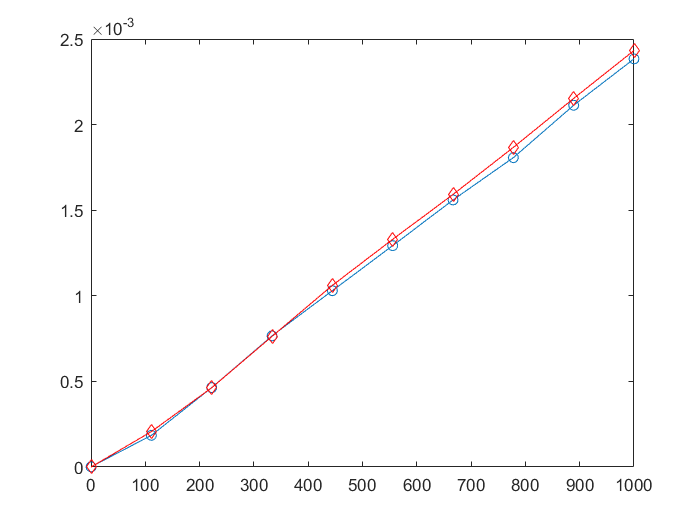

figure(h_p_3);
plot(t,p_t_int(3,:),'-dr')

fprintf('The elapsed time for 1 is %f seconds\n',elapsed_time_1);

The elapsed time for 1 is 328.782274 seconds


fprintf('The elapsed time for 2 is %f seconds\n',elapsed_time_2); 

The elapsed time for 2 is 7.123448 seconds
